clear;
syms a positive
syms b positive
syms x1 x2

% find equilibrium points
f1 = x1*(1 - x1 - a*x2);
f2 = b*x2*(x1-x2);

sln = solve([f1==0, f2==0], [x1 x2]);
sln.x1

$$ans = \left(\begin{array}{c} 0\\ 1\\ \frac{1}{a+1} \end{array}\right)$$

sln.x2

$$ans = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{a+1} \end{array}\right)$$


% jacobian
J = jacobian([f1 f2], [x1 x2])

$$J = \left(\begin{array}{cc} 1-a\,x_{2}-2\,x_{1} & -a\,x_{1}\\ b\,x_{2} & b\,\left(x_{1}-x_{2}\right)-b\,x_{2} \end{array}\right)$$

for i=1:numel(sln.x1)
    disp('===============================')
    disp('Equilibrium Point: ')
    disp([sln.x1(i) sln.x2(i)])
    A = subs(J,[x1 x2], [sln.x1(i) sln.x2(i)]);
    disp('Eigenvalues: ')
    disp(eig(A))
    disp('Eigenvalues at a=1, b=0.5: ')
    disp(subs(eig(A),[a b], [1 0.5]))
end

Equilibrium Point: 


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

Eigenvalues: 


$$\left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

Eigenvalues at a=1, b=0.5: 


$$\left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

Equilibrium Point: 


$$\left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

Eigenvalues: 


$$\left(\begin{array}{c} -1\\ b \end{array}\right)$$

Eigenvalues at a=1, b=0.5: 


$$\left(\begin{array}{c} -1\\ \frac{1}{2} \end{array}\right)$$

Equilibrium Point: 


$$\left(\begin{array}{cc} \frac{1}{a+1} & \frac{1}{a+1} \end{array}\right)$$

Eigenvalues: 


$$\left(\begin{array}{c} -\frac{b-\sqrt{b^{2}-4\,a\,b-2\,b+1}+1}{2\,\left(a+1\right)}\\ -\frac{b+\sqrt{b^{2}-4\,a\,b-2\,b+1}+1}{2\,\left(a+1\right)} \end{array}\right)$$

Eigenvalues at a=1, b=0.5: 


$$\left(\begin{array}{c} -\frac{3}{8}+\frac{\sqrt{7}\,\mathrm{i}}{8}\\ -\frac{3}{8}-\frac{\sqrt{7}\,\mathrm{i}}{8} \end{array}\right)$$

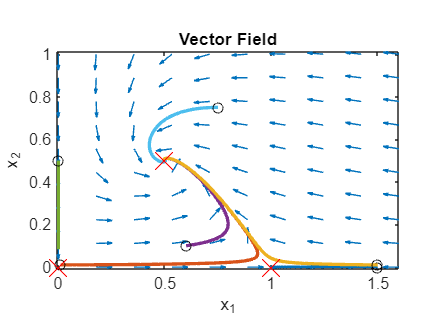

% Create vector field
x = linspace(0,1.6,10);
y = linspace(0,1,10);
[X,Y] = meshgrid(x,y);

a = 1;
b = 0.5;
DX = X.*(1 - X - a*Y);                 
DY = b*Y.*(X-Y);

N = sqrt(DX.^2 + DY.^2);
quiver(X,Y,DX./N,DY./N,0.4);
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title("Vector Field")
hold on;

% plot trajectories
for y0 = [0.01 0.01; 0.6 0.1; 0.75 0.75; 1.5 0; 1.5 0.01; 0 0.5]'
    [~, ys] = ode45(@f,[0 20],y0);
    plot(ys(:,1),ys(:,2),'-','LineWidth',2)
    plot(ys(1,1),ys(1,2),'ko')
end

% plot the eq. points
plot([0 1 1/(a+1)], [0 0 1/(a+1)], 'rx', 'MarkerSize',15)
hold off

function [y_dot] = f(~,y)
a = 1;
b = 0.5;
y_dot(1,:) = y(1)*(1-y(1)-a*y(2));
y_dot(2,:) = b*y(2)*(y(1)-y(2));
end